clc,clear

# **A CO2 model for climate simulation**

## variables definitions

five principal variables

- p: Partial pressure of carbo dioxide in the atmosphere

- sigma_s: total dissolved carbon concentration in the shallow ocean

- sigma_d: total dissolved carbon concentration in the deep ocean

- alpha_s: alkalinity in the shallow ocean

- alpha_d: alkalinity in the deep ocean

Equlibirum terms

- h_s: %hudrogen carbonate in the shallow ocean

- c_s: carbonate in the shallow ocean ocean

- p_s: partial pressure of gaseous carbon dioxide in the shallow ocean

f(t) is the source term due to burning of fossil fuels

%contants involved in this model

d = 8.64;
u_1 = 4.95*10^2;
u_2 = 4.95*10^(-2);
v_s = 0.12;
v_d = 1.23;
w   = 10^(-3);
k1  = 2.19*10^(-4);
k2  = 6.12*10^(-5);
k3  = 0.997148;
k_4 = 6.79*10^(-2);

%Initial Conditions at t=1000
IC_p = 1.00; % p
IC_sigma_S = 2.01; % sigma_s
IC_sigma_d = 2.23; % sigma_d
IC_alpha_s = 2.20; % alpha_s
IC_alpha_d = 2.26; % alpha_d

domain = [1000 5000]; %time domain for the ODEs, independant variable

IC = [IC_p, IC_sigma_S, IC_sigma_d, IC_alpha_s,IC_alpha_d]; %Taking initial conditions into a vector

# Question number 1)

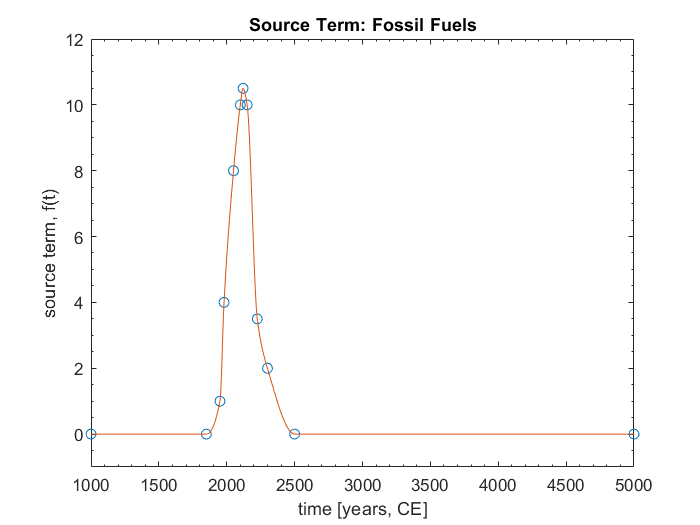

figure('Name', 'Question no.1 graph','NumberTitle','off');
t=2020;
f = sourceFossilFuels1(t); %This function iinterpolates the given points and output the relevant value for the year 2020.

disp('2020 source term value'),f

2020 source term value


f = 6.4702

# Question no.2) A)

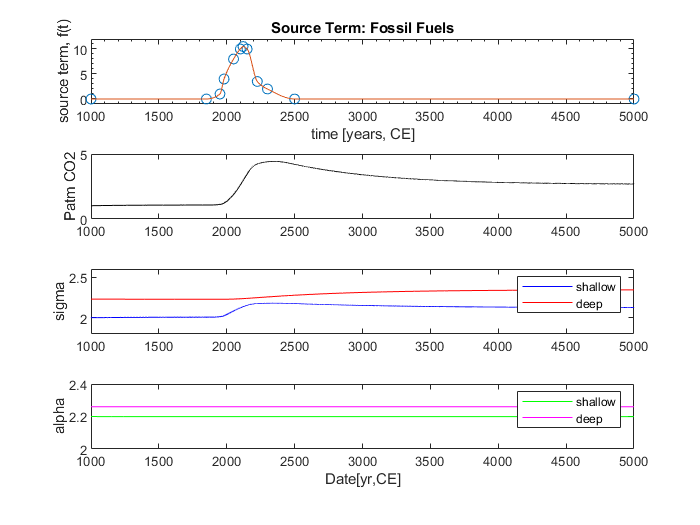

t=2020;
figure('Name', 'Question 2 graphs: trends','NumberTitle','off');
subplot(4,1,1);
f(t) = sourceFossilFuels1(t); %plotting the source term f(t)

[IVsol, DVsol] = ode23('DEdef', domain, IC); %Solving the system of ODEs. DEdef contains the equations

subplot(4,1,2);
plot(IVsol, DVsol(:,1), 'k'),ylabel('Patm CO2') % plotting partial pressure of the CO2 in the atmosphere
ylim([0,5])

subplot(4,1,3);
plot(IVsol, DVsol(:,2), 'b') % plotting sigma_s
hold on
plot(IVsol, DVsol(:,3), 'r'),ylabel('sigma') %plotting sigma_d
ylim([1.8,2.6])
legend('shallow', 'deep')
hold off

subplot(4,1,4);
plot(IVsol, DVsol(:,4), 'g') %plotting alpha_s
hold on
plot(IVsol, DVsol(:,5), 'm'),ylabel('alpha'),xlabel('Date[yr,CE]') %plotting alpha_d
ylim([2,2.4])
legend('shallow', 'deep')
hold off

# Question 2) B) answer

%Taking the year that atmospheric carbon dioxide reach it's maximum
[val, idx] = max(DVsol(:,1));
maximum_CO2_year = round(IVsol(idx))

maximum_CO2_year = 2345

# Question 3) A)

For the sawtooth, see the sigma in deep ocean(total dissolved carbon concentration in the deep ocean)magnify it, then you can see. Also following graphs has take out a range that clearly shows the sawtooth.

Oscillation type is 'traingular waves oscillation'

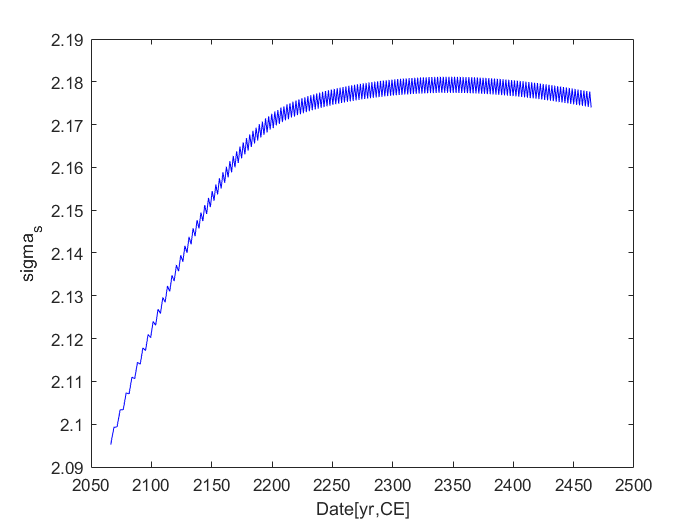

[IVsol, DVsol] = ode23('DEdef', domain, IC); %Solving the system of ODEs. DEdef contains the equations

%sawtooth 1
figure('Name', 'sawtooth example 1','NumberTitle','off');
%Defining the arrays for see a region contains a clear sawtooth
y_array = DVsol(:,2);
y_array = y_array(200:500);
x_array = IVsol(200:500);
plot(x_array, y_array , 'b'),ylabel('sigma_s'),xlabel('Date[yr,CE]') % sigma_s
ylim([2.09,2.19])

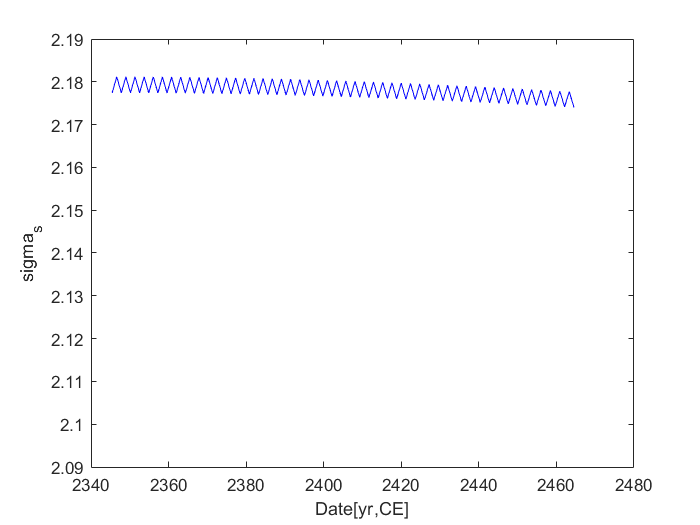


%sawtooth 2
figure('Name', 'Sawtooth example 2','NumberTitle','off');
%Defining the arrays for see a region contains a clear sawtooth
y_array = DVsol(:,2);
y_array = y_array(400:500);
x_array = IVsol(400:500);
plot(x_array, y_array , 'b'),ylabel('sigma_s'),xlabel('Date[yr,CE]')  % sigma_d
ylim([2.09,2.19])

# Question no. 3) B) first part

ode23, ode45, ode23s, ode113, ode23s, ode15s, ode23tb

Following 7 graphs graphs show how these ode solvers behave in this problem. Consider the elpased time, sawtooth and accuracy. Then you can comeup with the ode15s which is the best for this problem.

%Ode23 solver behavior
fprintf('ode23: ')

ode23: 

tic; [IVsol, DVsol] = ode23('DEdef', domain, IC); toc

Elapsed time is 3.868230 seconds.


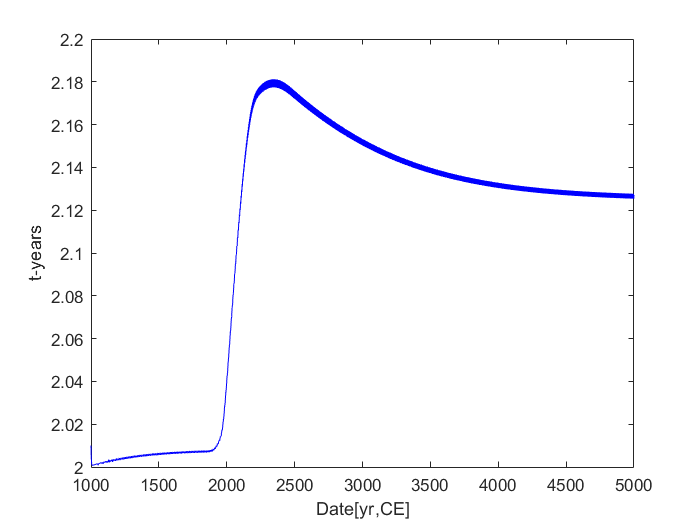

figure('Name','ode23 behavior','NumberTitle','off');
plot(IVsol, DVsol(:,2), 'b'),ylabel('t-years'),xlabel('Date[yr,CE]') 


%ode15s solver behavior
fprintf('ode15s: ')

ode15s: 

tic; [IVsol, DVsol] = ode15s('DEdef', domain, IC); toc 

Elapsed time is 0.329693 seconds.


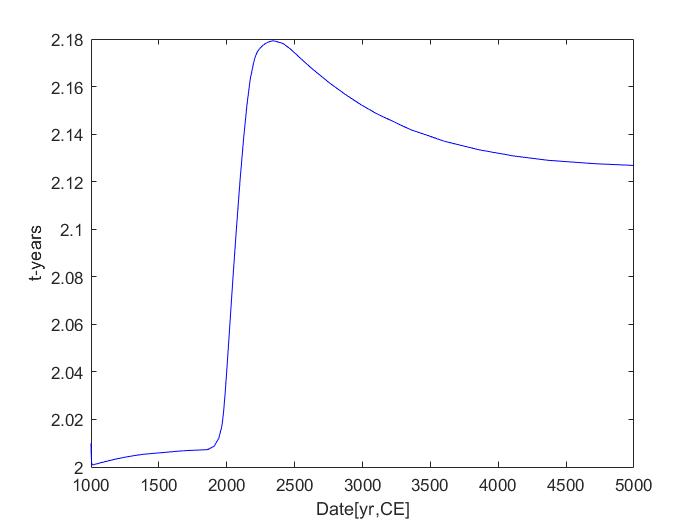

figure('Name','ode15s behavior','NumberTitle','off');
plot(IVsol, DVsol(:,2), 'b'),ylabel('t-years'),xlabel('Date[yr,CE]')


%ode23s solver behavior
fprintf('ode23s: ')

ode23s: 

tic; [IVsol, DVsol] = ode23s('DEdef', domain, IC); toc

Elapsed time is 0.343703 seconds.


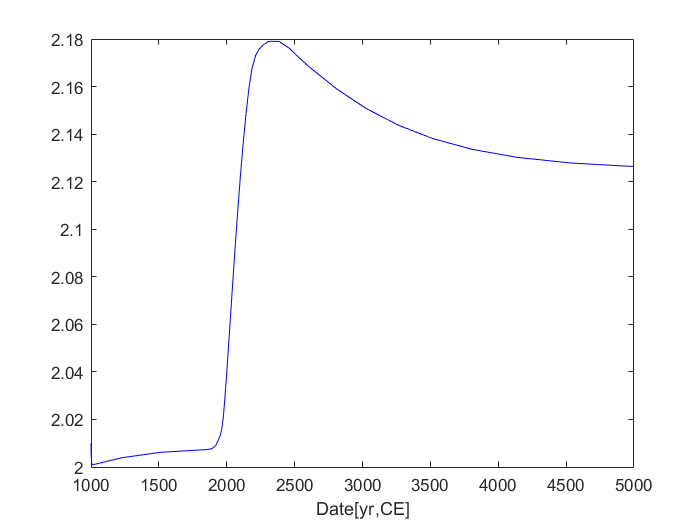

figure('Name','ode23s behavior','NumberTitle','off');
plot(IVsol, DVsol(:,2), 'b'),xlabel('Date[yr,CE]')


%ode45 solver behavior
fprintf('ode45: ')

ode45: 

tic; [IVsol, DVsol] = ode45('DEdef', domain, IC); toc

Elapsed time is 4.434899 seconds.


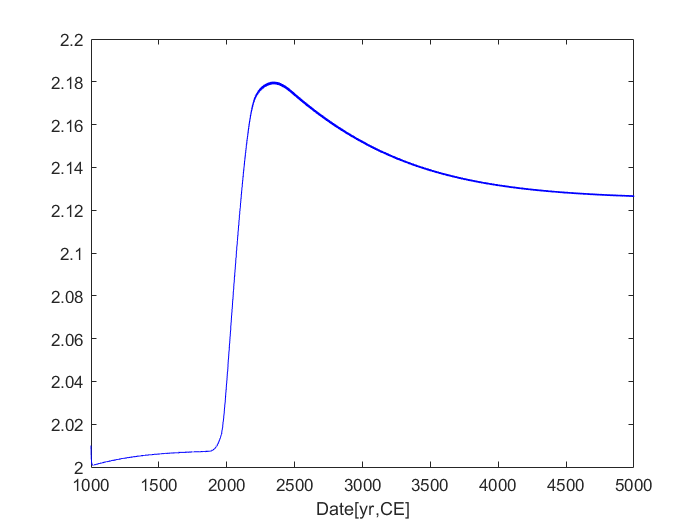

figure('Name','ode45 behavior','NumberTitle','off');
plot(IVsol, DVsol(:,2), 'b'),xlabel('Date[yr,CE]')


%ode113 solver behavior
fprintf('ode113: ')

ode113: 

tic; [IVsol, DVsol] = ode113('DEdef', domain, IC); toc

Elapsed time is 3.756645 seconds.


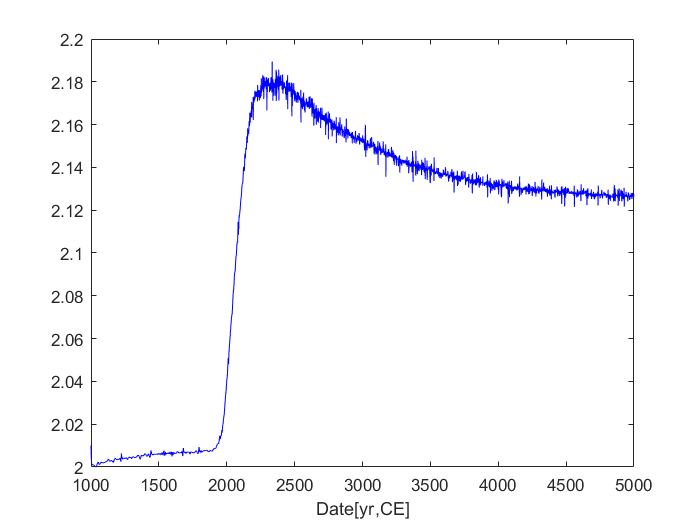

figure('Name','ode113 behavior','NumberTitle','off');
plot(IVsol, DVsol(:,2), 'b'),xlabel('Date[yr,CE]')


%ode23t solver behavior
fprintf('ode23t: ')

ode23t: 

tic; [IVsol, DVsol] = ode23t('DEdef', domain, IC); toc

Elapsed time is 0.172698 seconds.


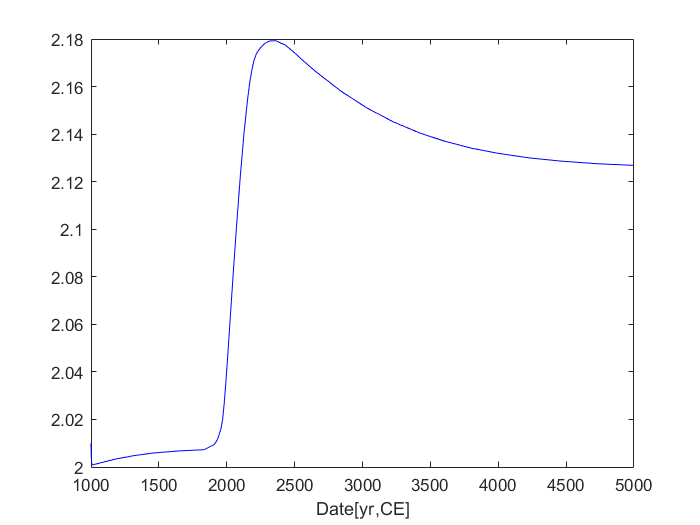

figure('Name','ode23t behavior','NumberTitle','off');
plot(IVsol, DVsol(:,2), 'b'),xlabel('Date[yr,CE]')  % sigma_s


%ode23tb solver behavior
fprintf('ode23tb: ')

ode23tb: 

tic; [IVsol, DVsol] = ode23tb('DEdef', domain, IC); toc

Elapsed time is 0.176286 seconds.


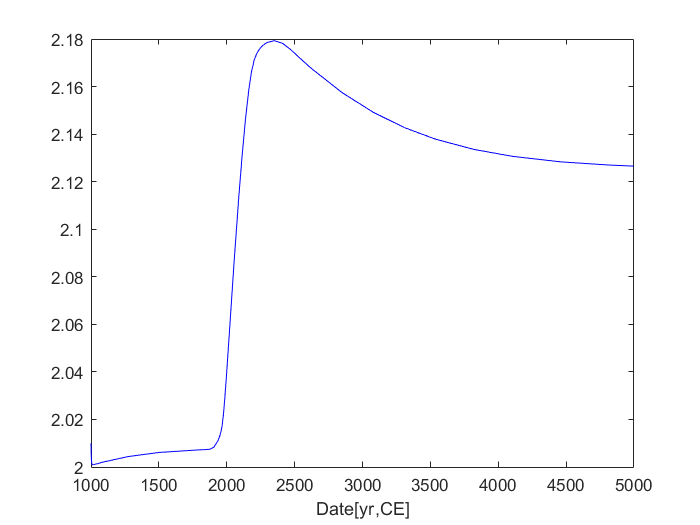

figure('Name','ode23tb behavior','NumberTitle','off');
plot(IVsol, DVsol(:,2), 'b'),xlabel('Date[yr,CE]')  % sigma_s

According to the elapsed time, printing on the command window, we can compare the computational costs. These 7 figures shows us how the ode solvers outputs ode15s is the best for this problem considering the computational cost and accuracy of the solution(no sawtooth)

# Question no. 3) B) second part

%Use varios tolerences take the details printing on the command window.
options = odeset('RelTol',1e-6,'AbsTol',1e-6,'stats','on');

%ode23 Solver
fprintf('ode23: ')

ode23: 

figure('Name','ode23','NumberTitle','off');
tic; ode23('DEdef', domain, IC, options); toc %Calculating the elpased time

2595 successful steps
596 failed attempts
9574 function evaluations
Elapsed time is 17.765195 seconds.


disp(" ")


%ode15s Solver
fprintf('ode15s: ')

ode15s: 

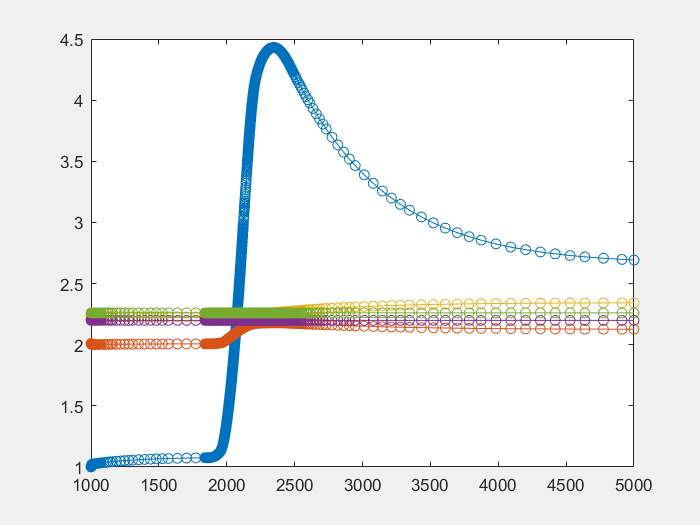

2480 successful steps
1141 failed attempts
5818 function evaluations
2 partial derivatives
1707 LU decompositions
5805 solutions of linear systems
Elapsed time is 11.013827 seconds.


figure('Name','ode15s','NumberTitle','off');
tic; ode15s('DEdef', domain, IC, options); toc %Calculating the elpased time

disp(" ")


%ode23s Solver
fprintf('ode23s: ')

ode23s: 

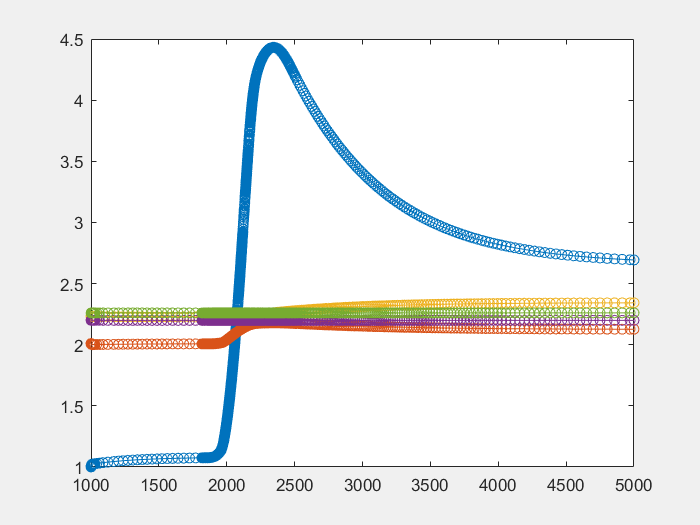

1543 successful steps
1242 failed attempts
14830 function evaluations
1543 partial derivatives
2785 LU decompositions
8355 solutions of linear systems
Elapsed time is 56.388278 seconds.


figure('Name','ode23s','NumberTitle','off');
tic; ode23s('DEdef', domain, IC, options); toc %Calculating the elpased time

disp(" ")


%ode45 Solver
fprintf('ode45: ')

ode45: 

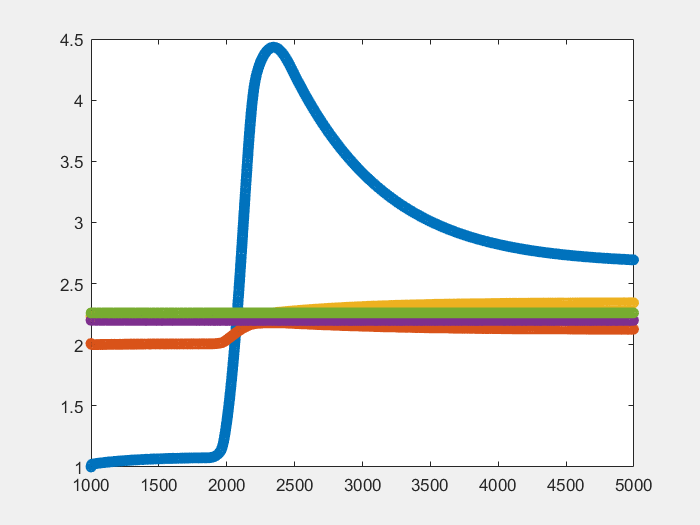

1734 successful steps
144 failed attempts
11269 function evaluations
Elapsed time is 13.826089 seconds.


figure('Name','ode45');
tic; ode45('DEdef', domain, IC, options); toc %Calculating the elpased time

disp(" ")


%ode113 Solver
fprintf('ode113: ')

ode113: 

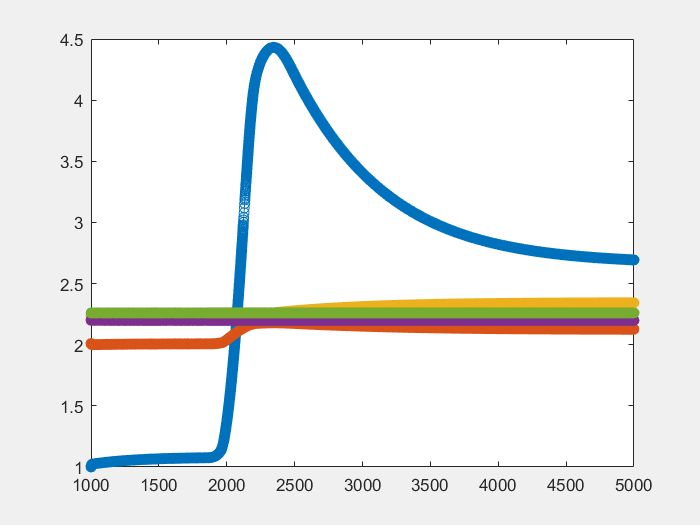

4673 successful steps
1512 failed attempts
10859 function evaluations
Elapsed time is 62.214087 seconds.


figure('Name','ode113','NumberTitle','off');
tic; ode113('DEdef', domain, IC, options); toc %Calculating the elpased time

disp(" ")


%ode23t Solver
fprintf('ode23t: ')

ode23t: 

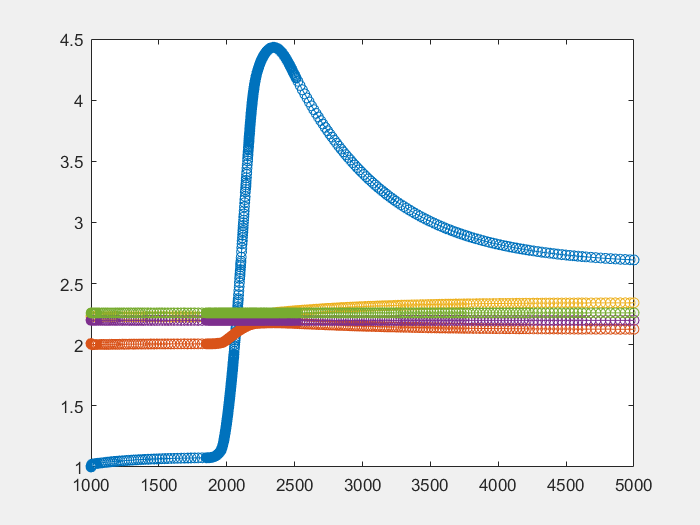

1132 successful steps
414 failed attempts
2627 function evaluations
3 partial derivatives
869 LU decompositions
2608 solutions of linear systems
Elapsed time is 10.619143 seconds.


figure('Name','ode23t','NumberTitle','off');
tic; ode23t('DEdef', domain, IC, options); toc %Calculating the elpased time

disp(" ")


%ode23tb Solver
fprintf('ode23tb: ')

ode23tb: 

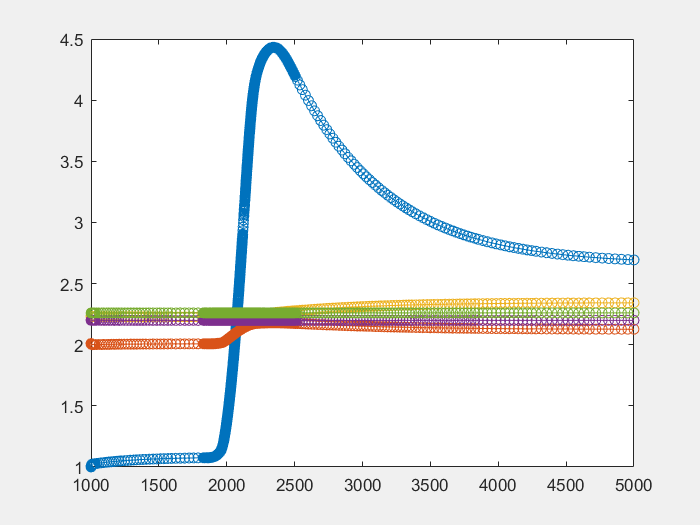

1936 successful steps
1276 failed attempts
9935 function evaluations
2 partial derivatives
2137 LU decompositions
13133 solutions of linear systems
Elapsed time is 14.520810 seconds.


figure('Name','ode23tb','NumberTitle','off');
tic; ode23tb('DEdef', domain, IC, options); toc %Calculating the elpased time

disp(" ")

# Question no 4

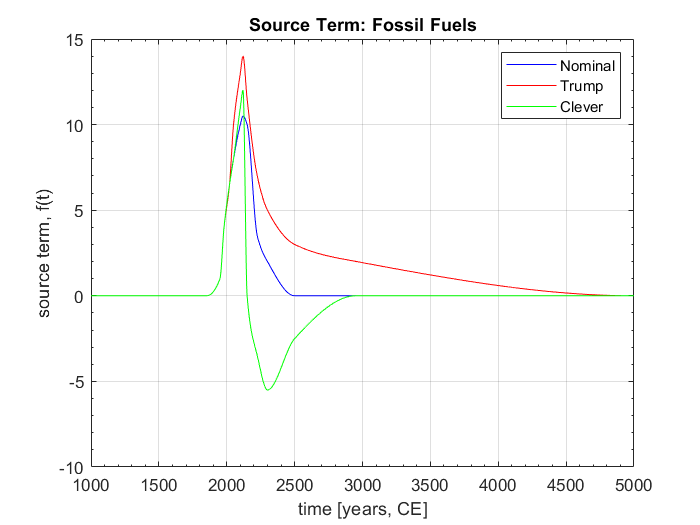

[rate1, rate2, rate3]=scenarios(2075);


%Rates at the 2075 for three scenarios
fprintf('nominal rate:'), rate1

nominal rate:

rate1 = 9.0555

fprintf('Trump wins :'), rate2

Trump wins :

rate2 = 11.6176

fprintf('Negative carbo :'), rate3

Negative carbo :

rate3 = 9.4429